clear;
clc;

#### 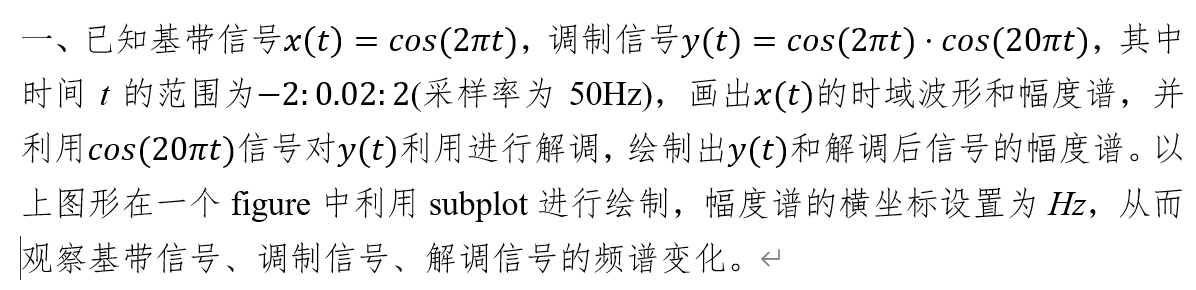

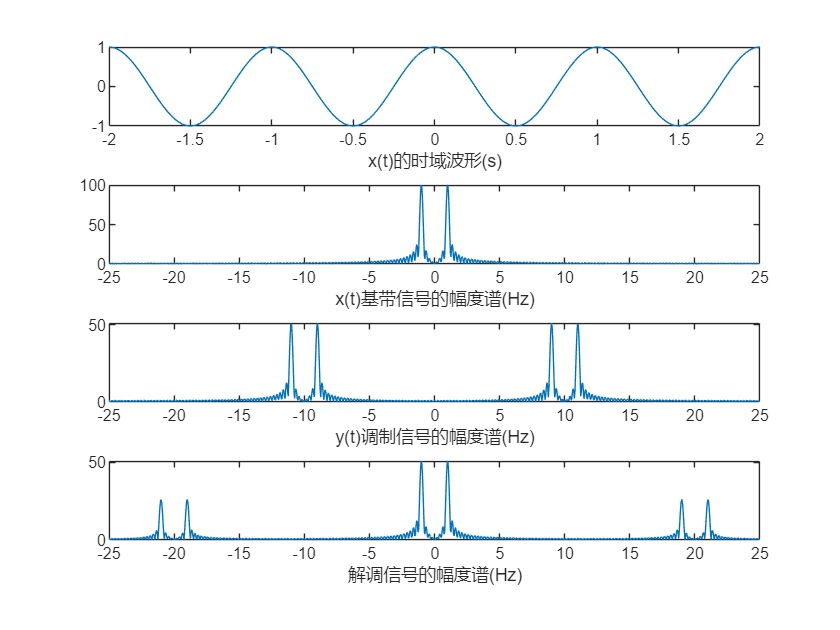

%%%%%%x(t)的时域波形和幅度谱%%%%%%
t=-2:0.02:2;
fs=50;
x=cos(2*pi*t);
F_pre=fft(x,1024);
F=fftshift(F_pre);% 将零频分量移到中间
figure(1);
subplot(4,1,1);
plot(t,x);
xlabel("x(t)的时域波形(s)");
subplot(4,1,2);
w=(-512:511)*fs/1024;
plot(w,abs(F));
xlabel("x(t)基带信号的幅度谱(Hz)");
%%%%%%y(t)的幅度谱%%%%%%
y=cos(2*pi*t).*cos(20*pi*t);
P_pre=fft(y,1024);
P=fftshift(P_pre);% 将零频分量移到中间
subplot(4,1,3);
plot(w,abs(P));
xlabel("y(t)调制信号的幅度谱(Hz)");
%%%%%%解调信号的幅度谱%%%%%%
q=y.*cos(20*pi*t);
Q_pre=fft(q,1024);
Q=fftshift(Q_pre);% 将零频分量移到中间
subplot(4,1,4);
plot(w,abs(Q));
xlabel("解调信号的幅度谱(Hz)");

clear;
clc;

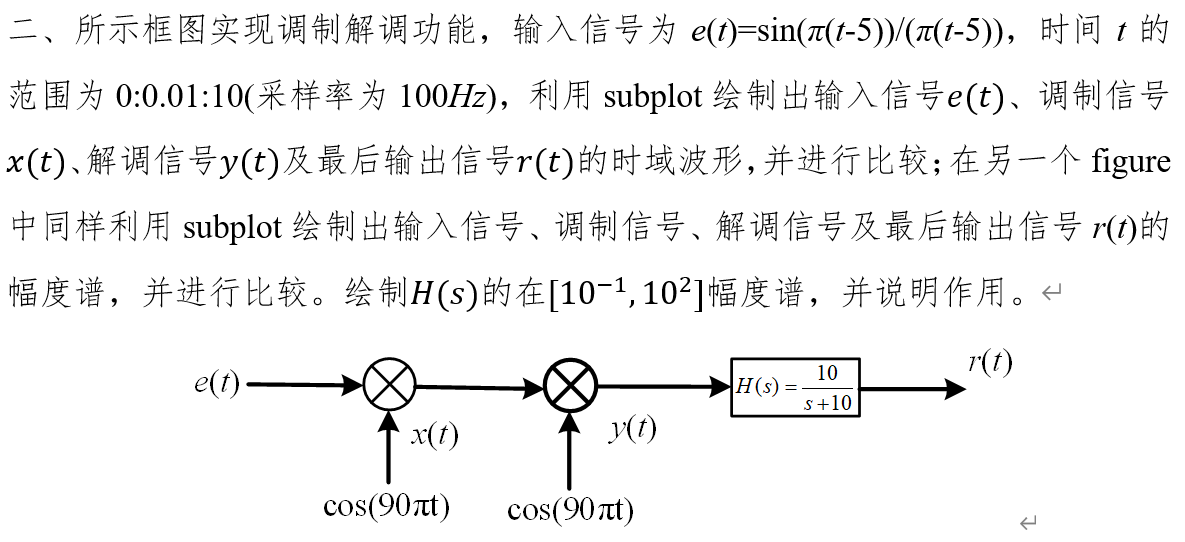

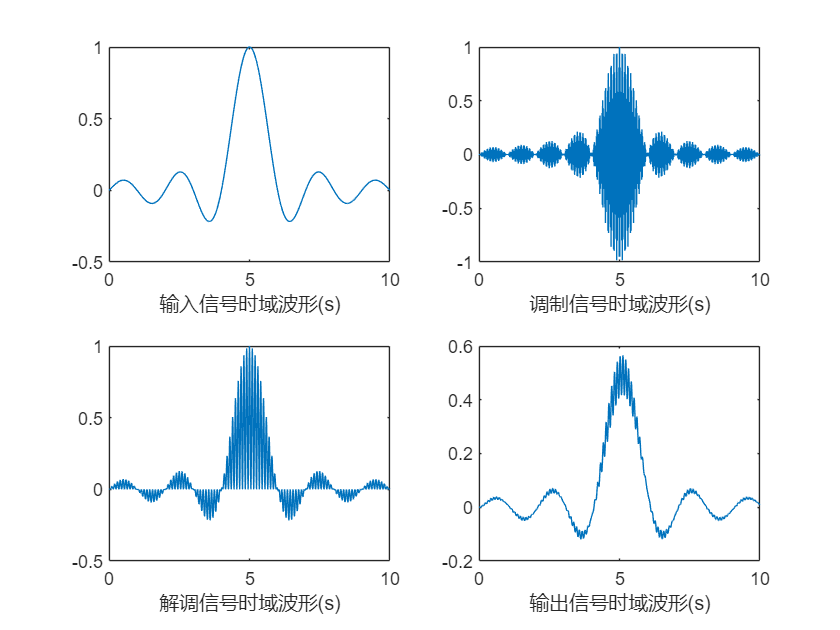

fs=100;
t=0:1/fs:10;
%%%%%输入信号%%%%%%
e=(sin(pi*(t-5))+eps)./(pi*(t-5)+eps);
E_pre=fft(e,1024);
E=fftshift(E_pre);
%%%%%调制信号%%%%%%
x=e.*cos(90*pi*t);
X_pre=fft(x,1024);
X=fftshift(X_pre);
%%%%%解调信号%%%%%%
y=x.*cos(90*pi*t);
Y_pre=fft(y,1024);
Y=fftshift(Y_pre);
%%%%%输出信号%%%%%%
A=[10];
B=[1 10];
sys=tf(A,B);%给定系统
r=lsim(sys,y,t);
R_pre=fft(r,1024);
R=fftshift(R_pre);
%%%%%时域波形%%%%%%
figure(2);
subplot(2,2,1);plot(t,e);xlabel('输入信号时域波形(s)');
subplot(2,2,2);plot(t,x);xlabel('调制信号时域波形(s)');
subplot(2,2,3);plot(t,y);xlabel('解调信号时域波形(s)');
subplot(2,2,4);plot(t,r);xlabel('输出信号时域波形(s)');

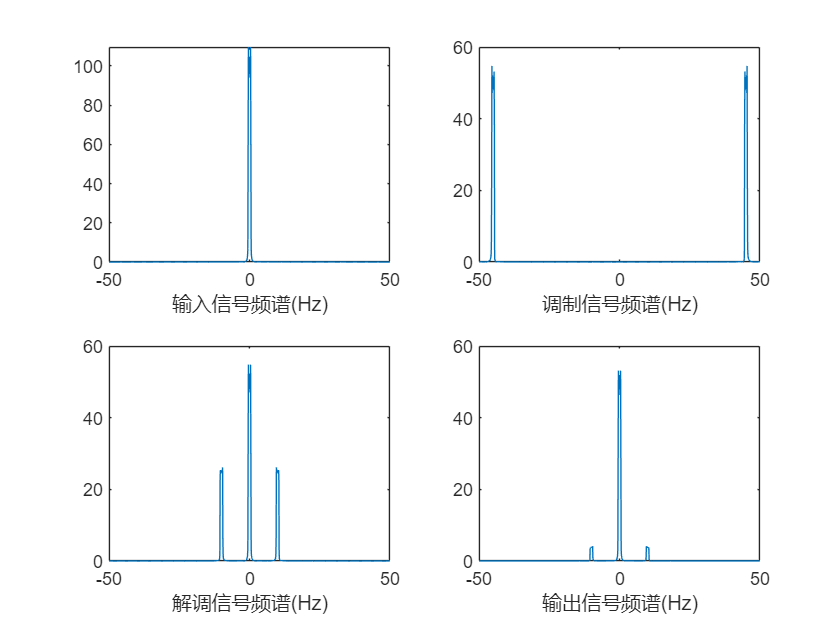

%%%%%幅度谱%%%%%%
w=(-512:511)*fs/1024;

%N=1024;
%w=(0:N-1)*fs/N-fs/2;%设置频率刻度

%point=512;
%w=(-point:point-1)*(1/fs/point/2);

figure();
subplot(2,2,1);plot(w,abs(E));xlabel('输入信号频谱(Hz)');
subplot(2,2,2);plot(w,abs(X));xlabel('调制信号频谱(Hz)');
subplot(2,2,3);plot(w,abs(Y));xlabel('解调信号频谱(Hz)');
subplot(2,2,4);plot(w,abs(R));xlabel('输出信号频谱(Hz)');

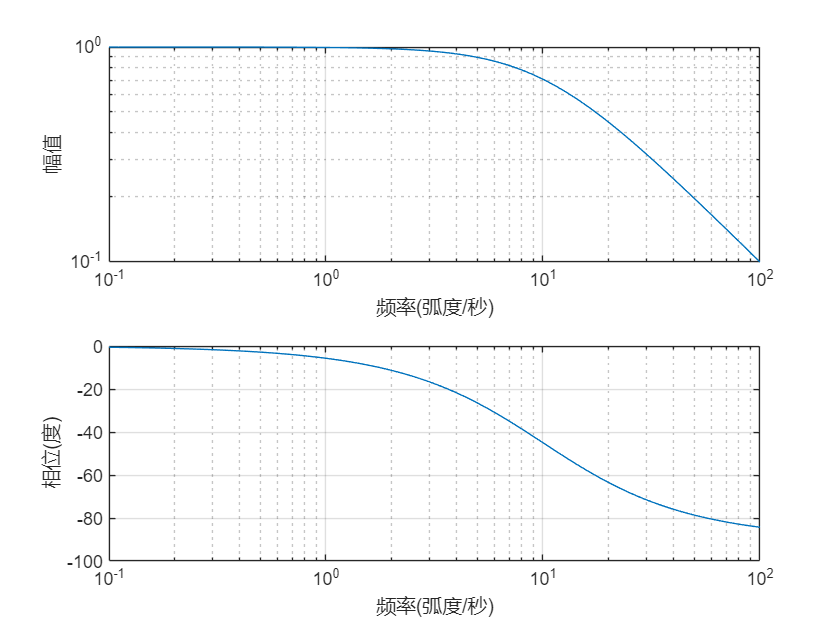

figure();
freqs(A,B);

clear;
clc;

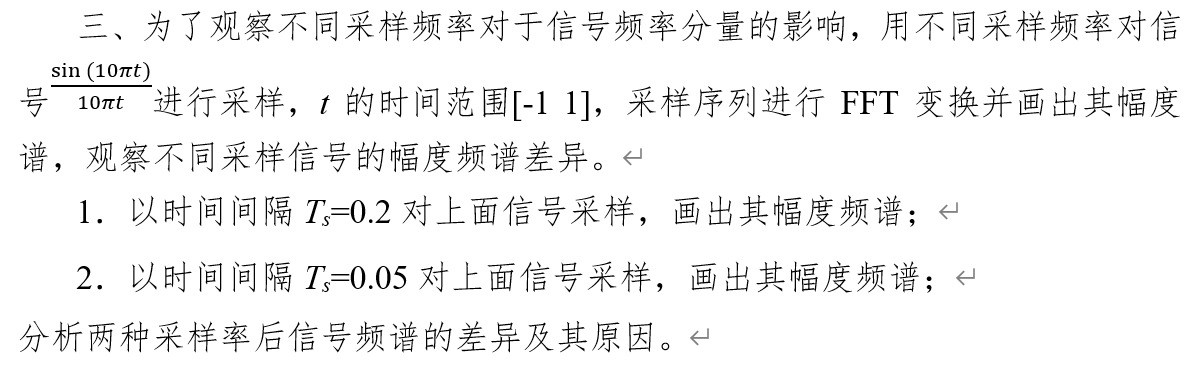

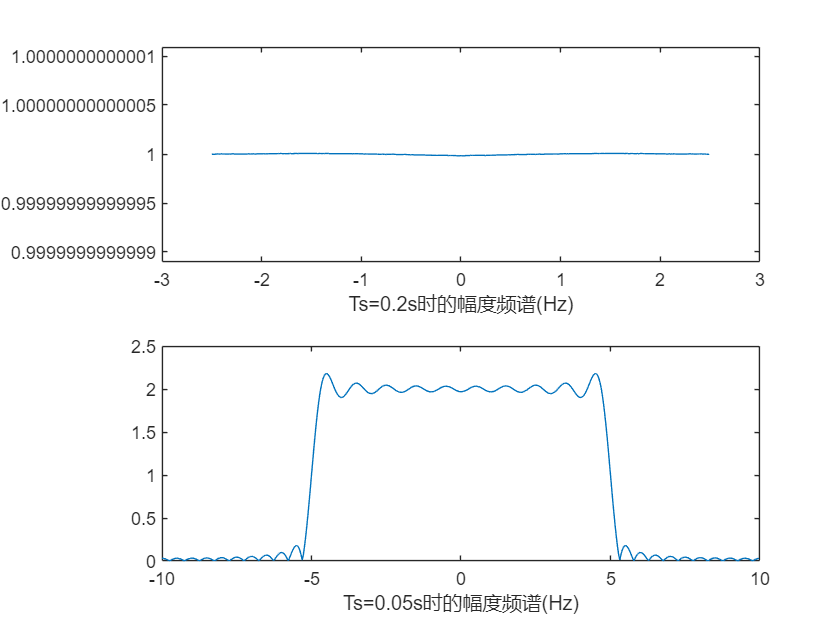

% 时间间隔
ts1=0.2; 
fs1=1/ts1; % 计算第一个采样频率
ts2=0.05; 
fs2=1/ts2; % 计算第二个采样频率
t1=-1:ts1:1;
t2=-1:ts2:1; 

% 频谱变换
f1=(sin(10*pi*t1)+eps)./(10*pi*t1+eps); % 计算第一个时间序列的频谱，使用sinc函数，eps避免除零
f2=(sin(10*pi*t2)+eps)./(10*pi*t2+eps); % 计算第二个时间序列的频谱
F1_pre=fft(f1,512); % 对第一个频谱进行快速傅里叶变换，长度为512
F1=fftshift(F1_pre); % 将FFT结果中心化
F2_pre=fft(f2,512); % 对第二个频谱进行快速傅里叶变换，长度为512
F2=fftshift(F2_pre); % 将FFT结果中心化

% 画图
figure(); % 创建新的图形窗口
w1=(-256:255)*fs1/512; % 计算第一个频谱的频率轴
subplot(2,1,1); % 在2行1列的子图中选择第一个位置
plot(w1,abs(F1)); % 绘制第一个频谱的幅度
xlabel('Ts=0.2s时的幅度频谱(Hz)'); 

w2=(-256:255)*fs2/512; % 计算第二个频谱的频率轴
subplot(2,1,2); % 在2行1列的子图中选择第二个位置
plot(w2,abs(F2)); % 绘制第二个频谱的幅度
xlabel('Ts=0.05s时的幅度频谱(Hz)'); 